# Evaluate Performance of Grid Forming Controls for Type 4 Wind Generators in Wind Farms

This project evaluates the capabilities of grid-forming (GFM) controller of type-4 wind turbine generators in maintaining a stable power system with high penetration of inverter-based renewable energy sources. 

Use this model to assess the dynamic performance of a wind farm during normal operation and contingencies, such as a large drop in wind power, load change, faults, and generatior trip. You can verify whether the GFM controller can help the wind farm to conform with the performance requirements that the industry standards recommend [1].

## System Overview

This figure shows the top-level schematic of the model. 

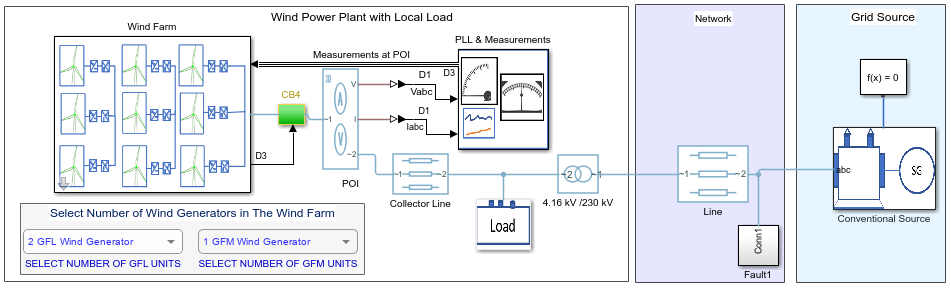

The wind farm can have a maximum of nine wind turbines. The turbines connect to type-4 wind turbine generators. Each wind turbine produces a maximum power of 6.1 MW at a rated wind speed of 11 m/sec. You can select the number of grid-following (GFL ) and GFM wind generator units in the wind farm using the dropdown boxes. By default, the wind farm has seven wind generation units operating with conventional GFL controllers and two wind generation units with GFM controllers. The GFL wind turbine generators operate at their maximum power point (MPP) using a phase-locked-loop (PLL)-based controller. This project models two ways to implement a virtual-synchronous-machine (VSM)-based GFM controller for grid-forming wind turbine generators.

This figure shows the wind turbine power characteristics.

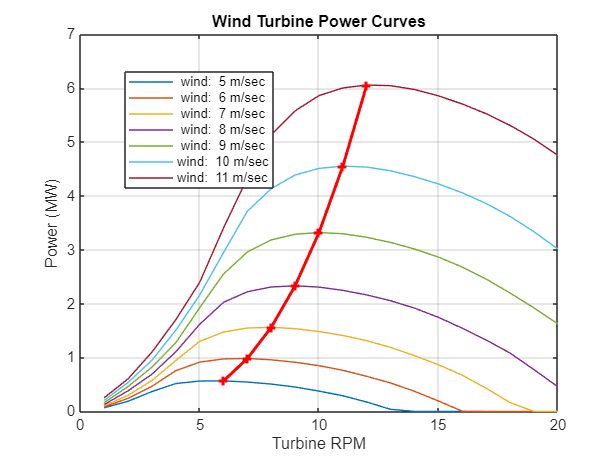

WindFarmGFMControlParameters;
plotPowerCurves;

### Type-4 Wind Turbine Generators

Two generators drive the utility-scale wind energy conversion systems:

- Type-3 generator with a double-fed induction generator (DFIG). 

- Type-4 generator with a permanent magnet synchronous generator (PMSG). 

PMSG-based type-4 generators comprise fully rated back-to-back power converters. These generators have high efficiency, power density, and reliability.  For instance, with a full-scale power converter the wind turbine and PMSG are decoupled from the grid and thus has a wider range of controllability for supporting the grid. This project focuses on the control of drictly-driven PMSG based type 4 wind turbine generators which eliminates the gearbox system from the wind turbines, thus reducing the maintenance cost and risk of gearbox failure. 

This figure shows the typical control architecture of a grid-connected PMSG-based type-4 wind generation system, the tubine, the PMSM, the machine-side converter (MSC), and the grid-side converter (GSC).

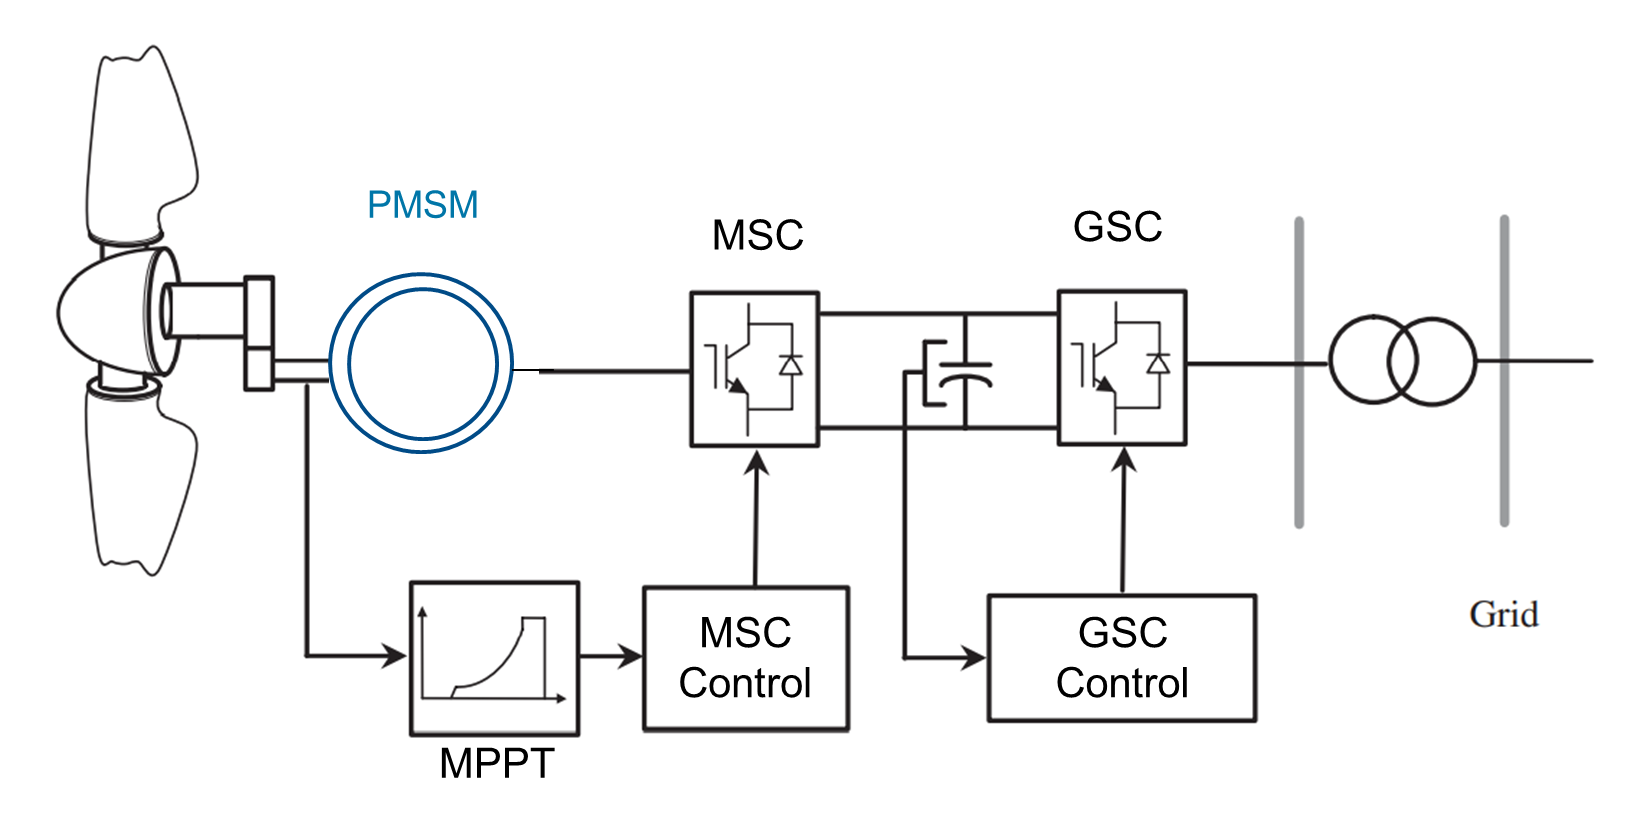

## Control of Type-4 Wind Turbine Generator

### GFL Controller 

In the GFL control model, the MSC extracts the maximum power from the wind turbine, and the GSC is responsible for maintaining the DC link voltage. The GSC uses a PLL and an inner current control loop to control the inverter output currents. The GFL wind turbine generator acts as a current source, and does not control the frequency and voltage magnitude.  The GFL controllers relies on the grid and other GFM sources to provide frequency and voltage references. The GFL controller performs voltage regulation at the point of interconnection (POI) using a Volt-VAR control strategy [2].

This figure shows the control structure of a GFL wind turbine generator.

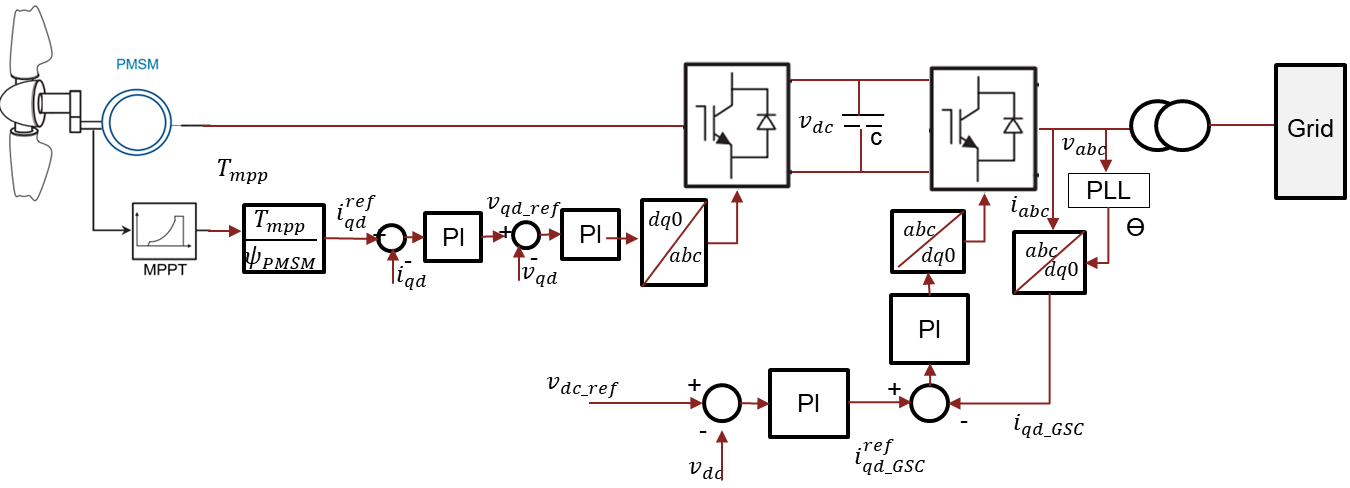

### GFM Controller 

Grid-forming (GFM) control of wind turbine generators makes the type-4 wind generator behave as a controllable voltage source behind an impedance. The GFM  controller can generate voltage and frequency reference without any measurements from the grid. This helps the wind farm to operate under weak grid conditions as the GFM controller resists changes (within limit) in voltage and frequency in the network by behaving as a voltage source. As the GFM inverters do not require an external reference voltage, it can even operate even when the main power grid is not present.

In some GFM inverters, an integrated storage, such as a battery pack, regulates the DC-link voltag. However, in a GFM wind turbine generator without any integrated storage, the GSC or the MSC can regulate the DC-link voltage. Thus, for wind turbine applications, you must take in consideration the DC-link voltage regulation for a GFM controller of a wind turbine generator. Based on the DC-link voltage control, there are two GFM control strategies for type-4 wind turbine generators:

- GFM control based on DC-link voltage regulation by GSC (G-GFM) 

- GFM control using turbine inertia with DC-link voltage control by MSC (M-GFM). 

This figures show the general control scheme for GFM control of wind turbine generators using G-GFM and M-GFM controllers.

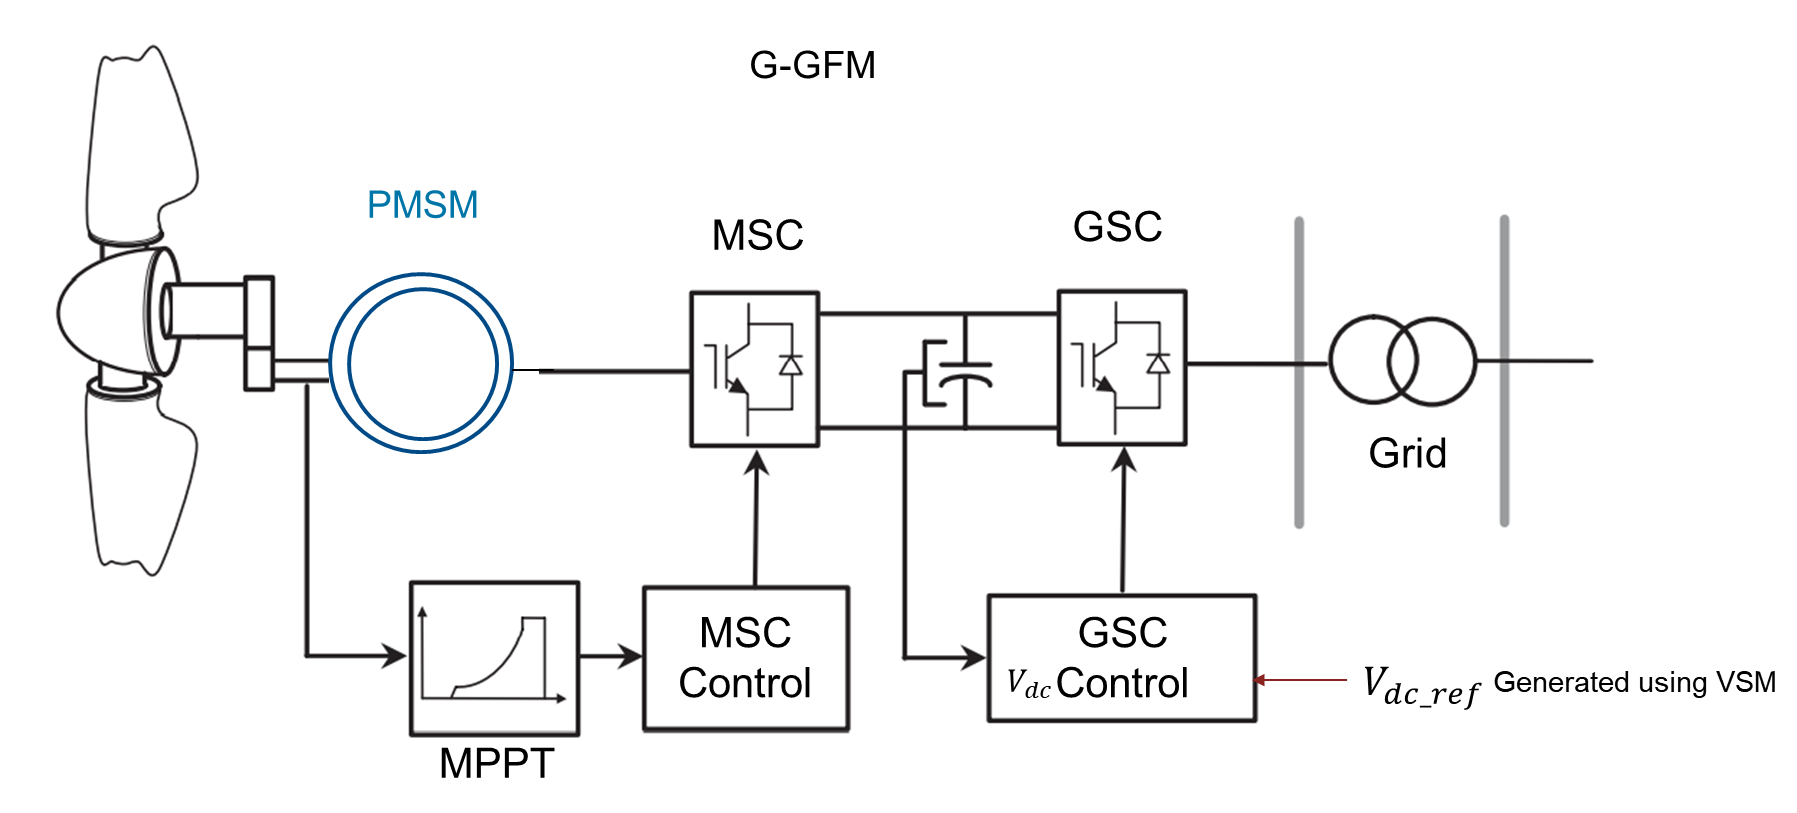   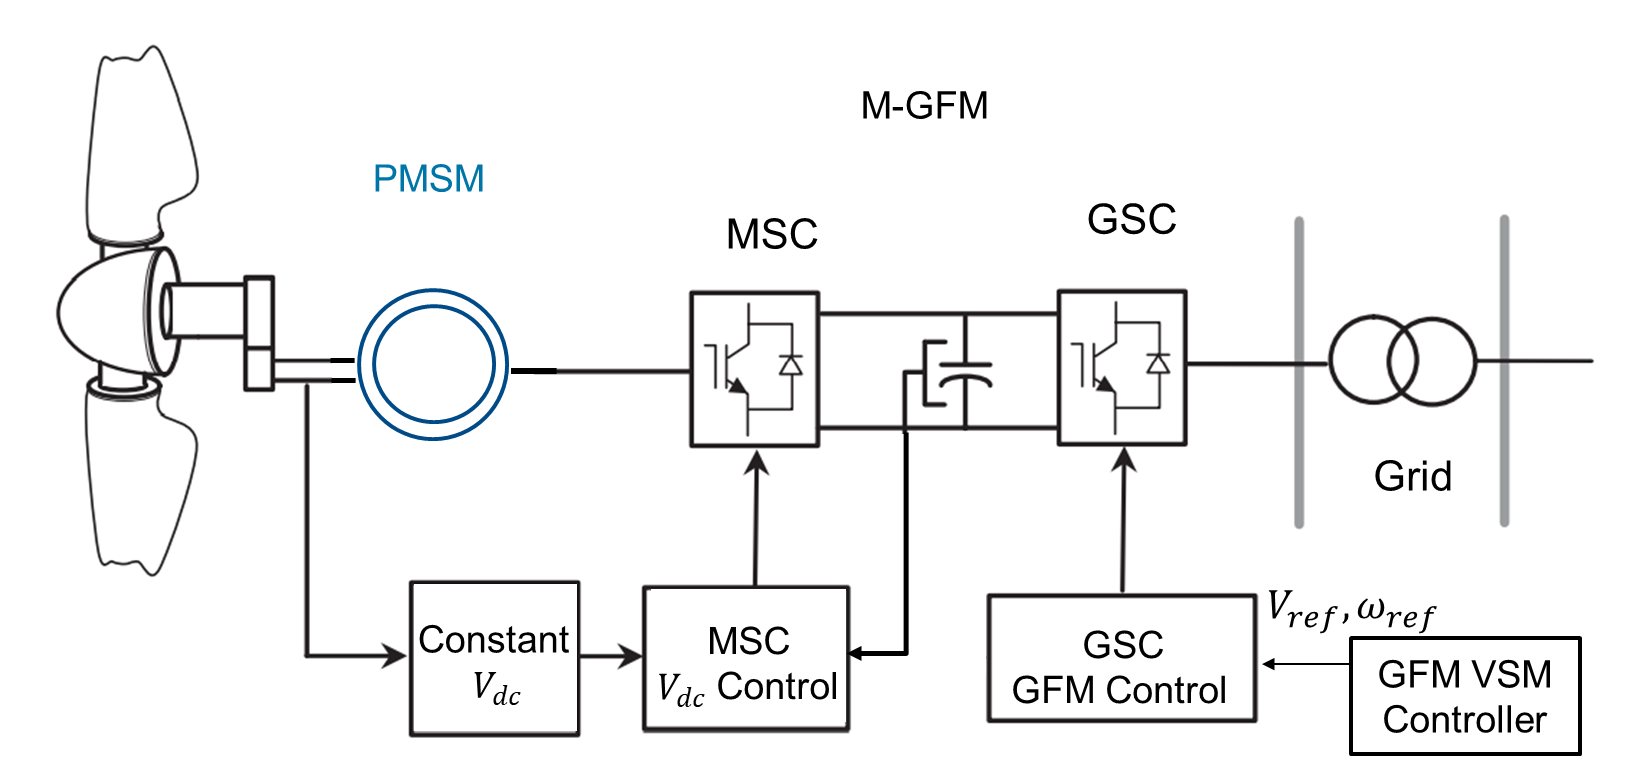

### 1) GFM using DC-Link Voltage Regulation by GSC (G-GFM)

Like the GFL control, the GFM controller uses the MSC to operate the wind turbine generator at its maximum power point (MPP) . However, the GSC is responsible for regulating the DC-link voltage using a VSM-based GFM control scheme [2]. The GSC controls the DC-link voltage and generates the instantaneous phase angle reference for the GSC controller. This controller provides the inertial response by allowing the variation of the DC-link voltage within a specified range.

This figure shows the GSC control architecture of the G-GFM control of the wind turbine generator. The MSC control architecture is the same as that of the GFL controller. 

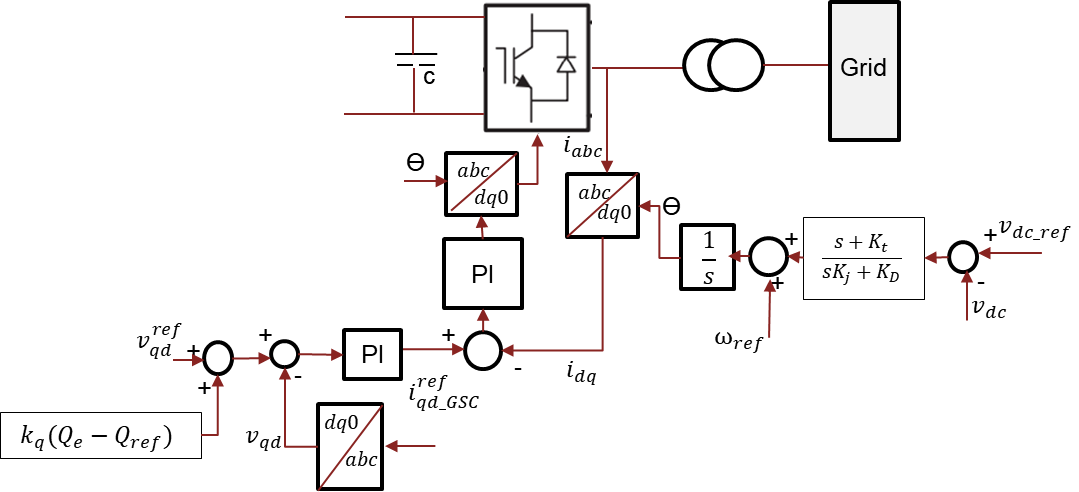

#### 2) **GFM using Turbine Inerta with DC-Link Volatge Control by MSC (M-GFM)**

This method uses the MSC to regulate the DC-link voltage, and the GSC is responsible for managing the output power. The GSC acts as a GFM inverter with a VSM based controller, which mimic the inertia and damping characteristic of synchronous generator [3].

This figure shows the control architecture of the M-GFM control of wind turbine generators.

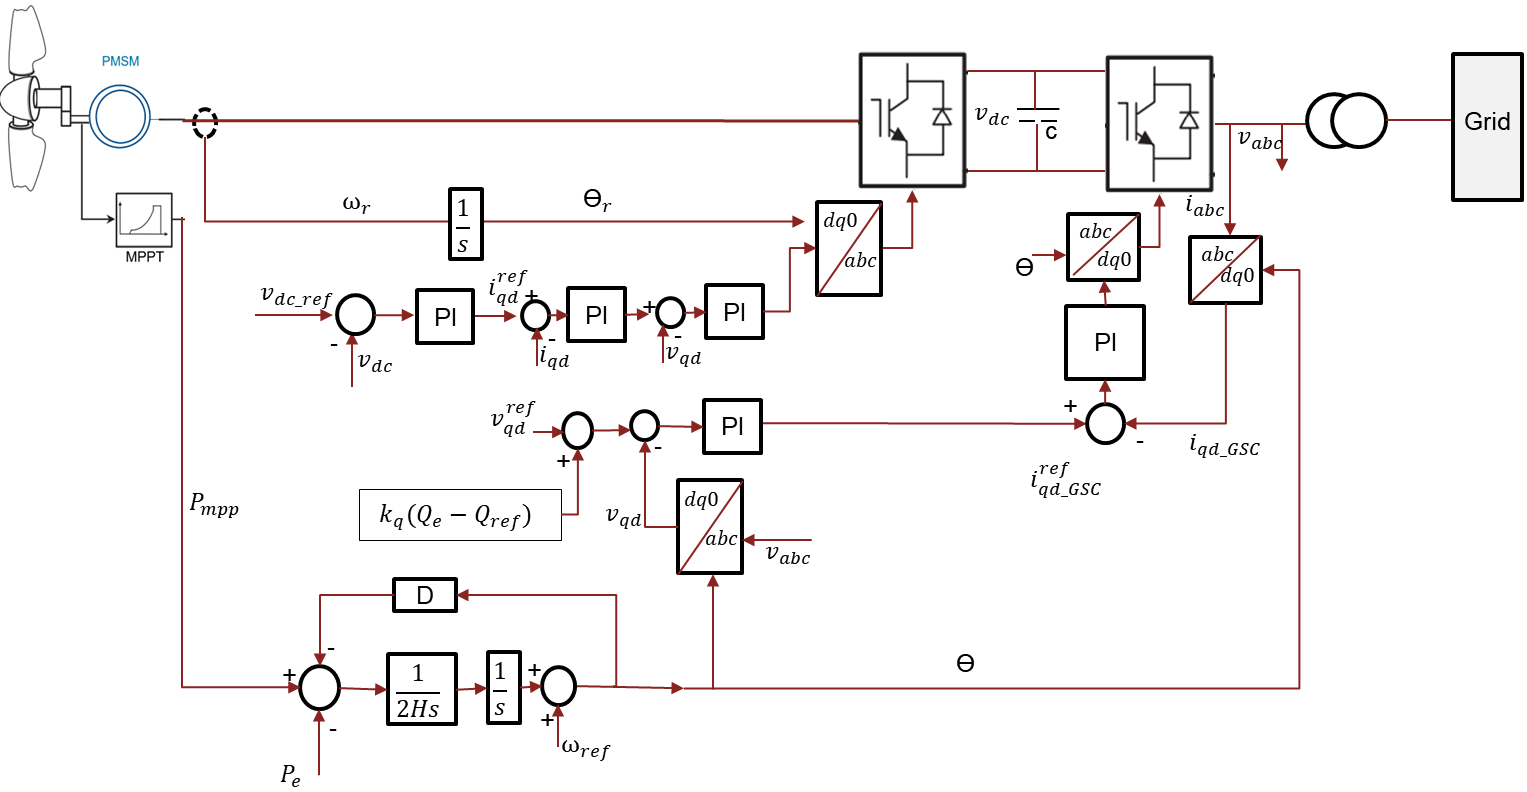

## Performance Requirements of Wind Turbine Generators 

This section describes the various interconnection requirements of a grid-connected wind farm that most grid codes recommend. 

You can check whether the wind turbine generator complies with the various grid code requirements, such as : fault ride through (FRT) requirements, system voltage and frequency limits, active power and frequency control requirements, and reactive power control and voltage regulation.

### Fault Ride-Through Requirements

Most standards, such as the Irish grid (ERI GRID) code [4], IEEE 2800 [1], recommend all inverter-based plants to provide voltage and frequency disturbance ride-through capability. 

Any unwanted tripping of the inverter-based resource (IBR) plant, due to IBR plant self-protection, as a direct or indirect result of a voltage or frequency disturbance within a ride-through region, constitutes non-compliance with standard practice. The simulation in this model uses the voltage and frequency ride-through characteristics that the standards recommend. During the ride-through period, the plant controller generates the reference current for the GFL inverters. 

The FRT requirements depend on the specific characteristics of each power system and are different from each other.                        

This figure shows the voltage ride-through requirements for the IBR plants as the IEEE 2800 standard recommends.

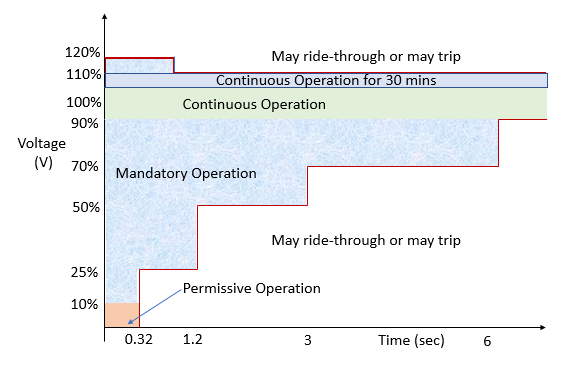

This table and this figure show the frequency ride through requirements.

TableII=readtable('BatteryStoragePVPlantGFMTRideThroughF.xlsx', ...
    'VariableNamingRule', 'preserve');
TableII = table(TableII,'VariableNames',{'Table: Frequency Ride-through Requirements [1]'});
disp(TableII)

                               Table: Frequency Ride-through Requirements [1]                           
    ____________________________________________________________________________________________________

    Frequency Range    Percent from Nominal    Minimum Ride-through Time (s)         Operating Mode     
    _______________    ____________________    _____________________________    ________________________
                                                                                                        
        {'f1'}                   3                          299                 {'Mandatory Operation' }
        {'f2'}                   2                          Inf                 {'Continuous Operation'}
        {'f3'}                  -2                          Inf                 {'Continuous O

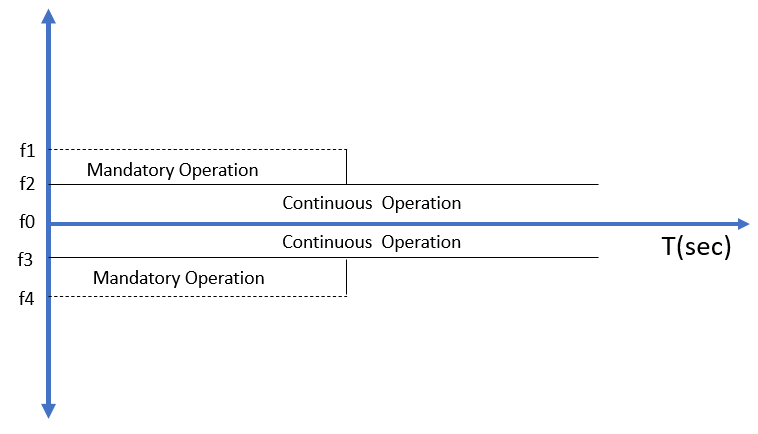

### Requirements on Voltage and Frequency 

#### Reactive Power and Voltage Control Requirements: 

When the voltage magnitude at the POI is within the continuous operating region (0.9 to 1.1 PU), the wind farm provides the voltage regulation by changing the reactive power output of the plant. The voltage control system performs reactive power droop to provide a stable and coordinated  response. 

#### Active Power and Frequency Control Requirements: 

The primary frequency response includes the capability to respond to under-frequency disturbances (by  active power increase) and over-frequency disturbances (by decreasing reactive power). 

In this example case, the GFM wind turbine generators provide inertial support, primary active power, and frequency control, to maintain a stable operation of the wind farm.

## Configure Model, Run Simulation, and Plot Results

### Simulation Settings

In this example, you test the performance of the wind farm by simulating these scenarios:

- **Wind Speed Variation **— Simulate a sudden reduction of wind power by curtailing the wind speed by 15%.

- **Large Load Change **— Simulate a sudden load change by increasing the load connected to the HV side of the plant transformer by 50 MW. 

- **Temporary Fault **— Create a three-phase-to-groung (LLLG) fault and clear it after 140 miliseconds.

- **Generation Outage**—Create a generation outage scenario by suddenly tripping six wind turbine generators connected to the wind farm

### Choose GFM Controller for Wind Turbine Generators

In this example, you can specify the GFM control strategy of the wind generator by selecting either the GFM using G-GFM or the M-GFM control archictures. You can select a GFM controller from the mask provided with the wind controller subsystem.

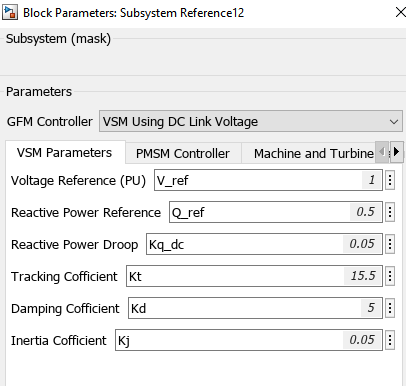

## Test Compliance with Standards under Various Operating Scenarios

### Choose Grid Code/ Standard to Test Compliance

You can evaluate whether the designed controllers for the wind turbines provide the adequate support to the grid such that the wind plant complies with the performance criteria that the standards recommends.

 In this section you can verify the compliance of the designed wind controllers with existing grid codes, such as the IEEE 2800 and the Irish grid code (ERI GRID). You can select eigther of the two grid codes from the dropdown list.

gridCode="IEEE 2800"

gridCode = "IEEE 2800"

This example uses short circuit ratio (SCR) as the metric to assess the system strength at the POI of wind plant [1]. 

- The SCR is the ratio between the three-phase short circuit Mega Volt Ampere (MVA) at a location to the Mega Watt ( MW) rating of the renewable source connected at that location. 


$$\textrm{SCR}=\frac{\textrm{Shot}\;\textrm{circuit}\;\textrm{MVA}\;\textrm{at}\;\textrm{POI}}{\textrm{MW}\;\textrm{of}\;\textrm{renewable}\;\textrm{power}\;\textrm{injected}\;\textrm{at}\;\textrm{POI}}$$


- A low SCR indicates a weak grid scenario, where the renewable source has the ability to significantly change the voltages and frequency at the POI.

### Evalution of GFM Wind Turbine Generator with DC-link voltage regulation by GSC (G-GFM)

%This code sets the model for tests with G-GFM Controller
mdl='WindFarmGFMControl';
open_system(mdl);
set_param('WindFarmGFMControl/Wind Farm/Wind Turbine (GFM)','Control','VSM Using DC Link Voltage');
set_param('WindFarmGFMControl/Wind Farm/Wind Turbine (GFM)1','Control','VSM Using DC Link Voltage');
wController=' with G-GFM Wind Controller'; 

**Calculate SCR at POI**

WindSCRCal;          % Calculation of SCR
sCR2=sCR.SCR;        % %Calculated SCR at POI
disp(['Calculated SCR at POI: ',num2str(sCR.SCR)]);

Calculated SCR at POI: 0.059668


**Performance during a sudden Change in Wind Power**

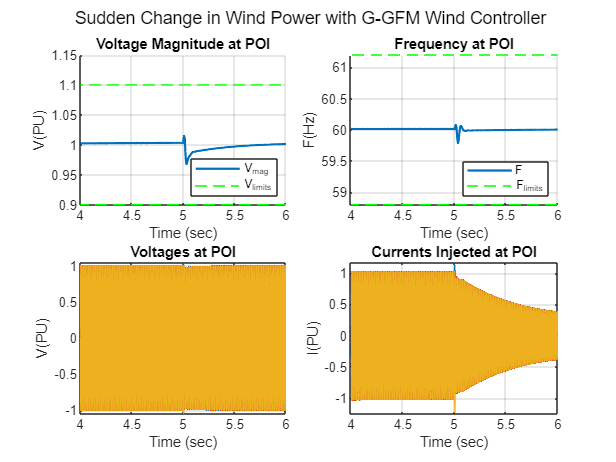

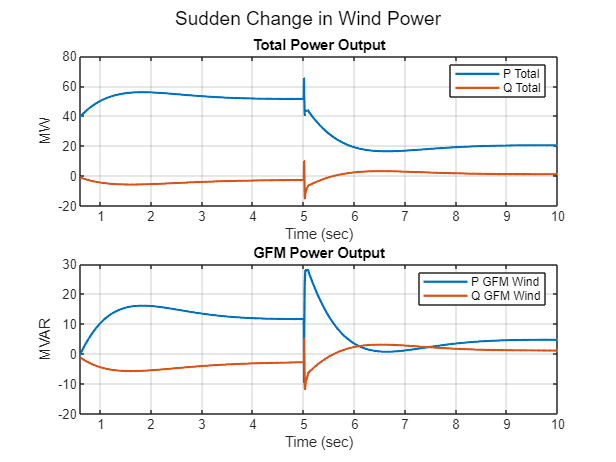

% Setting the parameters to simulate the event 
scenarioNumber=1; %#ok<*NASGU>
time.wind=tevent;
time.load=Tsim+1;
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults;

From the simulation results you can observe the response of the wind plant with GFM control during the disturbance. A stable volatge and a stable frequency indicate that the wind plant is able to provide the active inertial power and the primary response along with required reactive power to maintain stable system operation.

**Performance During Change in Load**

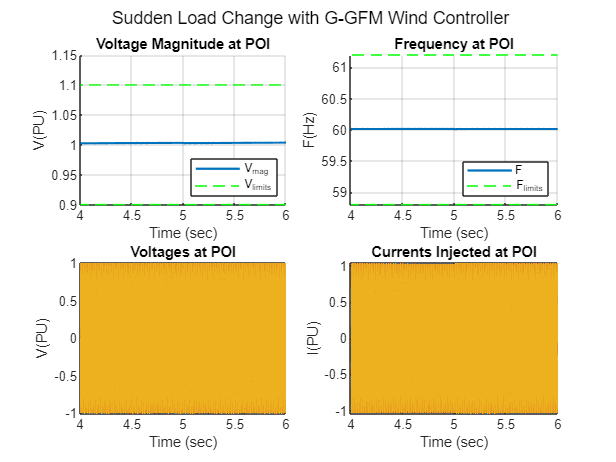

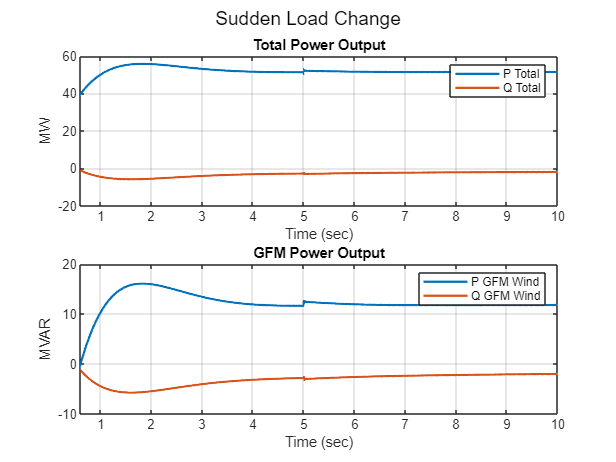

% Setting the parameters to simulate the event 
scenarioNumber=2;
time.wind=Tsim+1;
time.load=tevent;  
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults;

A load change scenario is created by increasing the 230 KV load by 50MW at 1.2 sec. From the simulation results you can see the response of the wind plant with GFM control during the disturbance. A stable volatge and a stable frequency indicates that the GFM wind source meets the increased load and maintains the voltage and frequency within the desirable limits.

**Performance During Fault**

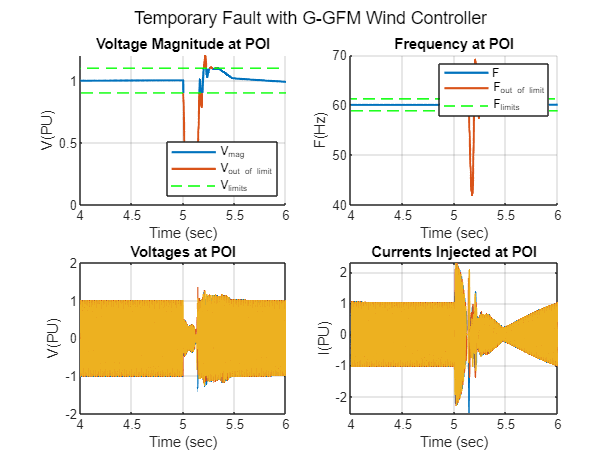

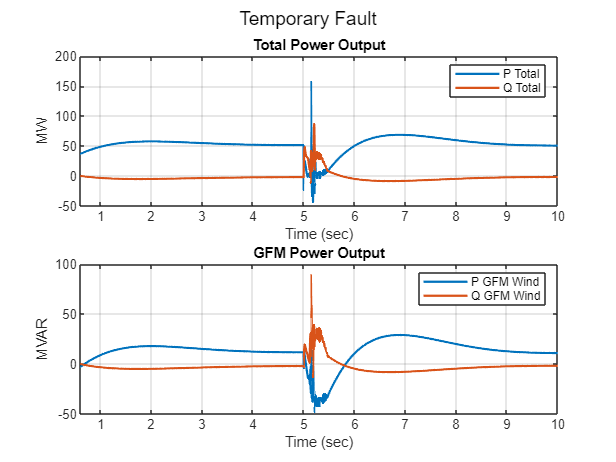

% Setting the parameters to simulate the event 
scenarioNumber=3;
time.wind=Tsim+1;
time.load=Tsim+1;
time.fault=tevent;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults;

observe the response of the GFM wind generator during a three-phase (LLLG) fault at the transmission line at 1.2 seconds. The fault clears after 140 ms. From the simulation results you can see the response of the wind plant during the disturbance. A stable volatge and a stable frequency indicates that the wind plant is able to ride-through low voltage and frequency variation during the fault, which is in compliance with the ride-through requirements in the standards. 

**Performance During Generation Outage**

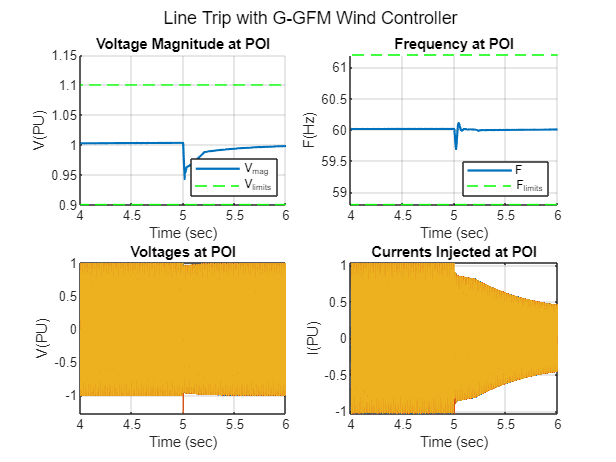

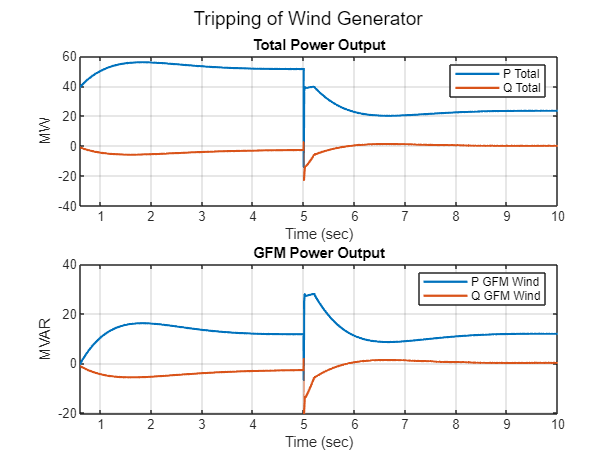

% Setting the parameters to simulate the event 
scenarioNumber=5;
time.wind=Tsim+1;
time.load=Tsim+1;
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=tevent;
WindGFMControlPlotresults;

By tripping six wind generators in the wind farm, you simulate a wind generation outage scenario. From the simulation results you can observe the response of the  wind plant with GFM control during the disturbance, a stable volatge and a stable frequency indicates that GFM controller is able to deliver the power and maintain voltage and frequency within the acceptable limits that the standards recommend.

### Evalution of GFM using Wind Turbine Inertia and voltage regulation by MSC (M-GFM)

%This code sets the model for tests with M-GFM Controller
mdl='WindFarmGFMControl';
open_system(mdl);
set_param('WindFarmGFMControl/Wind Farm/Wind Turbine (GFM)','Control','VSM Using Turbine Inertia');
set_param('WindFarmGFMControl/Wind Farm/Wind Turbine (GFM)1','Control','VSM Using Turbine Inertia');
wController=' with M-GFM Wind Controller';

**Performance During a Sudden Change in Wind Power**

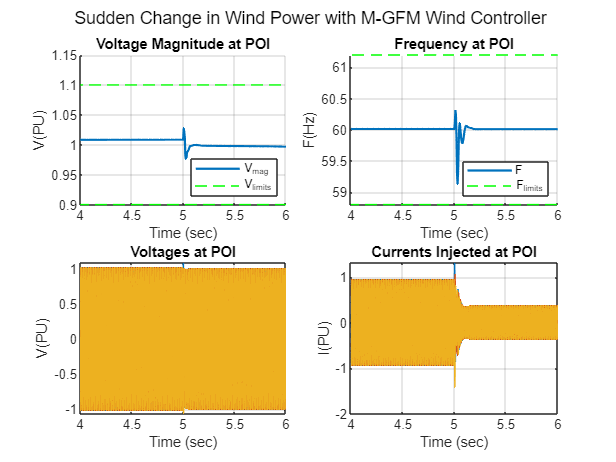

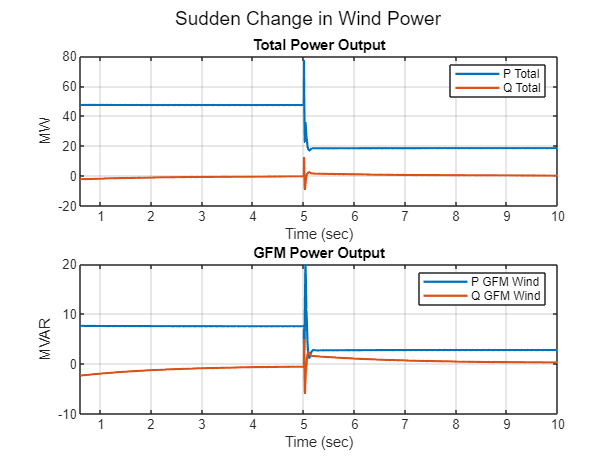

% Setting the parameters to simulate the event 
scenarioNumber=1;
time.wind=tevent;
time.load=Tsim+1;
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults; 

From the simulation results you can observe the response of the wind plant with GFM controller during the disturbance, a stable volatge and a stable frequency indicates that GFM controller is able to provide the active inertial power, the primary response, and reactive power to maintain stable system operation.

**Performance During a Sudden Change in Load**

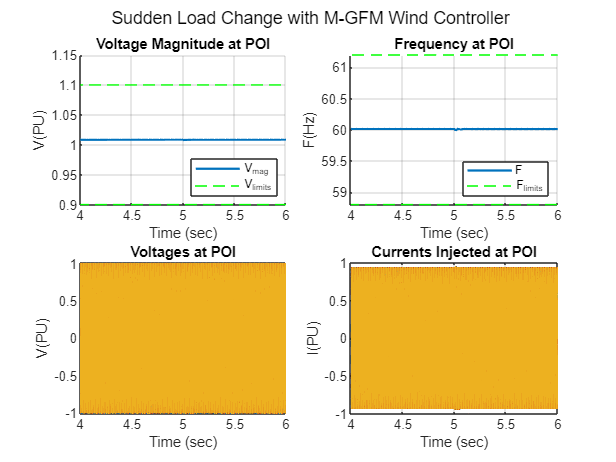

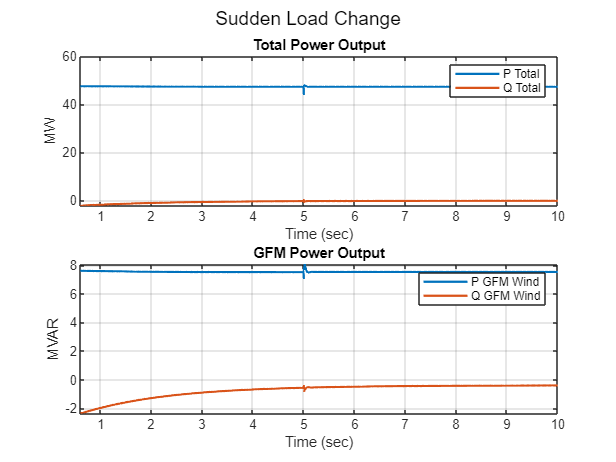

% Setting the parameters to simulate the event 
scenarioNumber=2;
time.wind=Tsim+1;
time.load=tevent;
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults;

A load change scenario is created by increasing the 230 KV load by 50MW at 1.2 sec. You can observe the response of the GFM wind controller. A stable volatge and a stable frequency indicates that GFM controller is able to meet the increased power demand and maintain voltage and frequency within the acceptable limits.

**Performance During Temporary Fault**

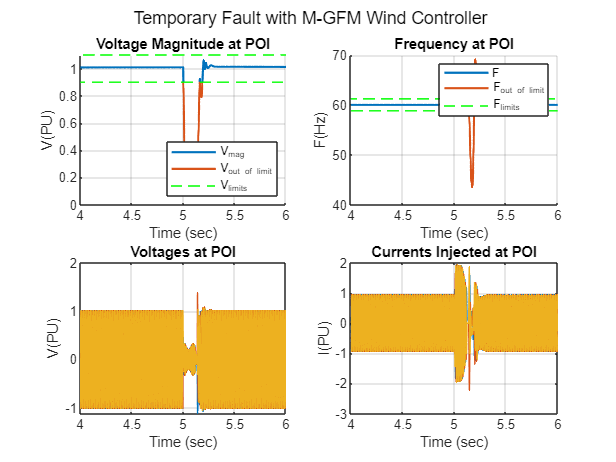

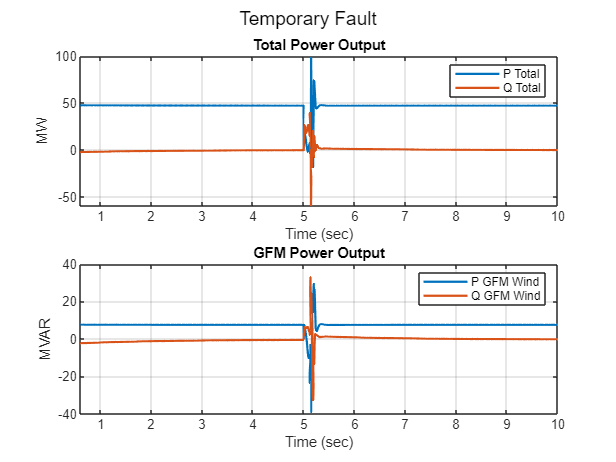

% Setting the parameters to simulate the event 
scenarioNumber=3;
time.wind=Tsim+1;
time.load=Tsim+1;
time.fault=tevent;
time.island=Tsim+1;
time.lineTrip=Tsim+1;
WindGFMControlPlotresults;

Observe the response of the GFM wind turbine unit during a three-phase (LLLG) fault occuring at the transmission line at 1.2 seconds. The fault clears after 140 ms. From the simulation results you can see the response of the wind plant during the disturbance, a stable volatge and a stable frequency indicates that the wind plant is able to ride-through low voltage and frequency variation during the fault, which is in compliance with the ride-through requirements in standards. Once the fault is cleared, if the system returns to its pre-fault state within 1 sec, then it is in compliance with the post-fault recovery requirements of the standard. 

**Performance During Generation Outage**

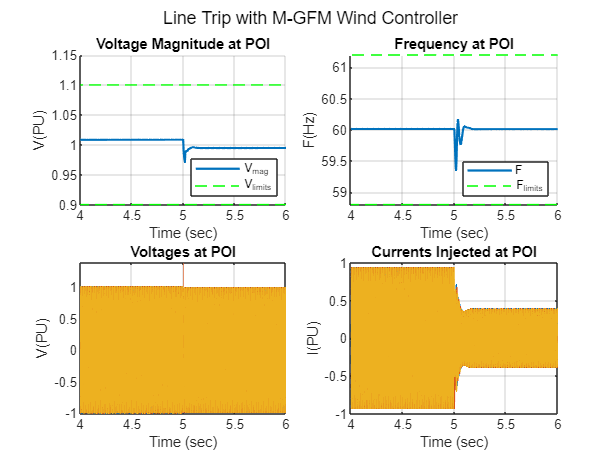

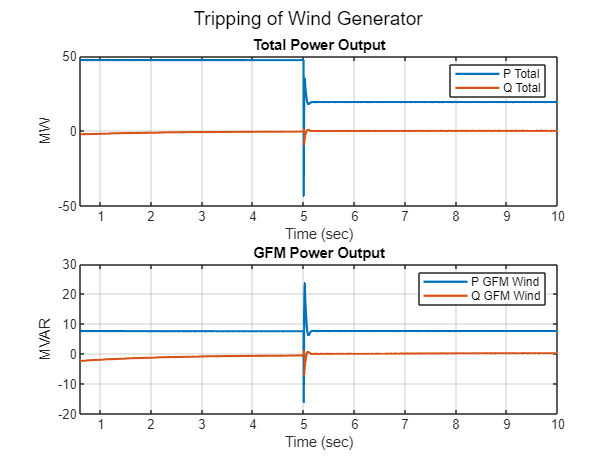

% Setting the parameters to simulate the event 
scenarioNumber=5;
time.wind=Tsim+1;
time.load=Tsim+1;
time.fault=Tsim+1;
time.island=Tsim+1;
time.lineTrip=tevent;
WindGFMControlPlotresults;

By tripping six wind generators in the wind farm, you simulate a wind generation outage scenario. From the simulation results you can observe the response of the  wind plant with GFM control during the disturbance. A stable volatge and a stable frequency indicates that the GFM controller is able to deliver the power and maintain voltage and frequency within the acceptable limits that the standards recommend.

This table shows the list of the design compliance criteria that the wind farm controller must verify during the various operating scenarios.

disp(TableIII)

                             Table: Compliance on Key Criteria mentioned in Standards                         
    __________________________________________________________________________________________________________

                   Requirements                                 Recommendations [1]                  Satisfied
    __________________________________________    _______________________________________________    _________
                                                                                                              
    {'Reactive Power Capability'             }    {'Q (minimum) as percentage of rated power'   }     {'✓'}  
    {'Voltage & Recative Power Control Modes'}    {'Reactive power droop control'               }     {'✓'}  
    {'Primary Frequency Response'            }    {'Provide frequency response'         

## Performance of Wind Plant with GFM and GFL Control for Varying Grid Strength

This section compares the performance of GFL wind controllers with GFM controllers for maintaining a stable grid under challenging operating conditions. 

You can vary he grid strength by chaging the length of the parallel transmission lines that connects the wind farm to the grid.

**Compare GFL and GFM Control Strategies of Wind Turbines for Strong Grid Condition**

This section verifies the performance of the wind farm with GFL and GFM controller in a relatively strong grid, with a SCR value greater than 3 at the POI, by creating a sudden change in wind speed at 1.2 sec. 

%Setting the parameters to simulate the event 
line.length1=1.5;  % Line length in Km
WindSCRCal;           % Calculation of SCR
sCR1=sCR.SCR;      %Calculated SCR at POI
disp(['Calculated SCR at POI: ',num2str(sCR1)]);

Calculated SCR at POI: 1.9038


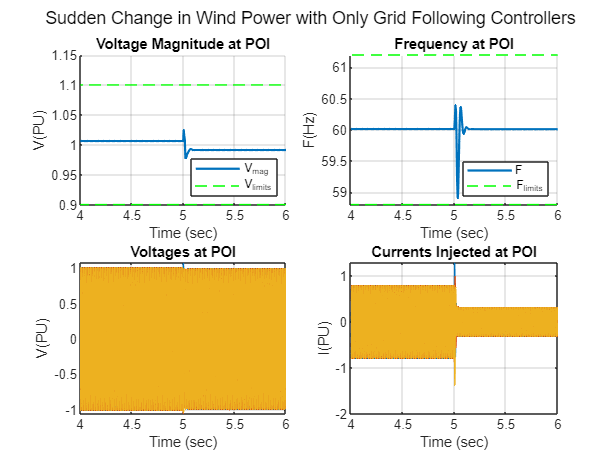

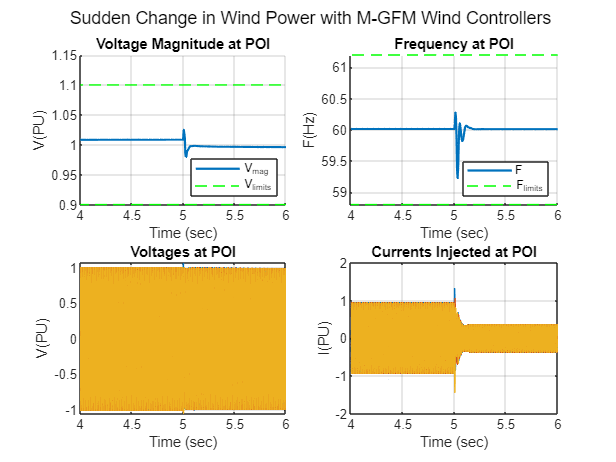

ComparisonGFMWithGFL

This figure shows that, when the wind farm connects to a strong grid, both the GFL and GFM controllers maintain a stable operation even in the presence of a sudden disturbance.

**Compare GFL and GFM Control Strategies of Wind Turbines for Weak Grid condition**

This section verifies the performance of wind farm with GFL and GFM controller in a weak grid interconnection, with an SCR value lower than 1, a sudden change in wind power at 1.2 sec.

The grid strength at the POI is reduced by increasing the length of the transmisssion lines that connect the wind farm to the conventional source.

%Setting the parameters to simulate the event 
line.length1=300;  % Line length in Km
WindSCRCal;          % Calculation of SCR
sCR2=sCR.SCR;     %Calculated SCR at POI
disp(['Calculated SCR at POI: ',num2str(sCR2)]);

Calculated SCR at POI: 0.020112


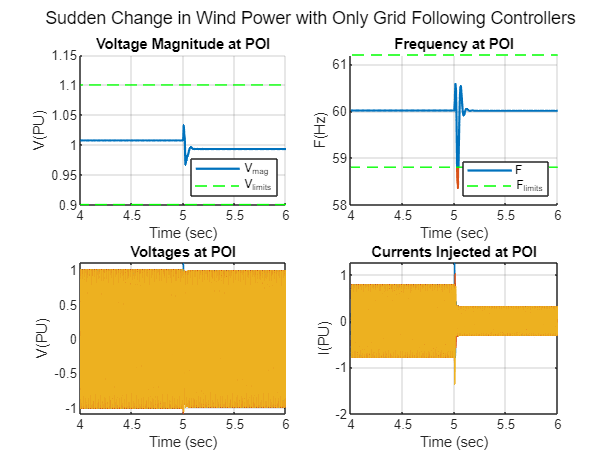

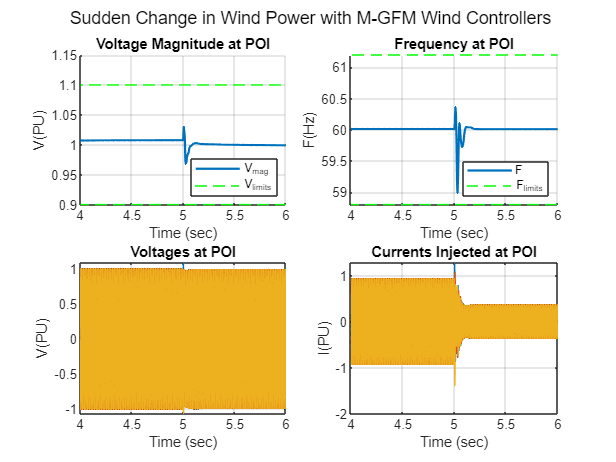

ComparisonGFMWithGFL

In a weak grid with the conventional GFL control, the voltage and frequency at the POI are eigther not within the limits or they start to oscillate after the disturbance. However, the GFM control of wind generators maintains steady voltage and frequency during and after the disturbance. The GFM controller provides the voltage and frequency response required to maintain a stable power system with high wind penetration in weak grid conditions.

This table summarizes the comparative assessments with the M-GFM control and with the GFL control. The results are obtained with a change in wind speed under varying grid strength at the POI.

TableIV=readtable('GFMvsGFLwithSCR.xlsx', ...
    'VariableNamingRule', 'preserve');
TableIV = table(TableIV,'VariableNames',{'Table:M-GFM vs GFL Control with Varying SCR at POI'});
TableIV.(1)(1,1).('Grid Strength (SCR)')=sCR1;
TableIV.(1)(2,1).('Grid Strength (SCR)')=sCR1;
TableIV.(1)(3,1).('Grid Strength (SCR)')=sCR2;
TableIV.(1)(4,1).('Grid Strength (SCR)')=sCR2;
disp(TableIV);

        Table:M-GFM vs GFL Control with Varying SCR at POI     
    ___________________________________________________________

    Grid Strength (SCR)          Control              Status   
    ___________________    ____________________    ____________
                                                               
           1.9038          {'Grid Following'  }    {'Stable'  }
           1.9038          {'Grid Forming VSM'}    {'Stable'  }
         0.020112          {'Grid Following'  }    {'Unstable'}
         0.020112          {'Grid Forming VSM'}    {'Stable'  }



## References

[1] [IEEE 2800 Standard for Interconnection and Interoperability of Inverter-Based Resources (IBRs) Interconnecting with Associated Transmission Electric Power Systems](https://standards.ieee.org/ieee/2800/10453/).

[2] [J. He, K. Wu, L. Huang, H. Xin, C. Lu, and H. Wang, “A coordinated control scheme to realize frequency support of pmsg-based wind turbines in weak grids,” in 2018 IEEE Power & Energy Society General Meeting (PESGM). IEEE, 2018, pp. 1–5.](https://ieeexplore.ieee.org/document/8586541)

[3] [Y. Wang, J. Meng, X. Zhang, and L. Xu, “Control of pmsg-based wind turbines for system inertial response and power oscillation damping,” IEEE Transactions on Sustainable Energy, vol. 6, no. 2, pp. 565–574, 2015.](https://ieeexplore.ieee.org/document/7042817)

[4] [Grid Code Version 12 (The Irish Grid Code)](https://www.eirgridgroup.com/site-files/library/EirGrid/GridCode.pdf)

Copyright 2023 The MathWorks, Inc.